% define the variables
m_cart = 0.5;
m_ball = 0.2;
b = 0.1;
g = 9.8;
l_rod = 0.3;
% define the A matrix
A=[0 1 0 0 ;
0 -b/m_cart -(m_ball*g)/m_cart 0;
0 0 0 1;
0 b/(m_cart*l_rod) ((m_cart+m_ball)*g)/(m_cart*l_rod) 0]

A =          0    1.0000         0         0
         0   -0.2000   -3.9200         0
         0         0         0    1.0000
         0    0.6667   45.7333         0


B=[0;1/m_cart;0; -1/(m_cart*l_rod)]

B =          0
    2.0000
         0
   -6.6667


C=[1 0 0 0];
D=0;
[num,den]=ss2tf(A,B,C,D);
T=tf(num,den);
pole(T);
eig(A);
% --- LQR Design ---
% Q: Weighting states [x, x_dot, theta, theta_dot]
% We care most about theta (3rd state), so we give it a higher weight.
Q = [1 0 0 0;
     0 1 0 0;
     0 0 200 0;
     0 0 0 10];


% R: Weighting the force input.
R = 0.4;


% Calculate the optimal gain K
K_lqr = lqr(A, B, Q, R);


% calculating the static feedforward control parameters
% 1. Create Augmented Matrices
A_aug = [A, zeros(4,1); -C, 0];
B_aug = [B; 0];

% 2. Define 5x5 Q matrix (give the 5th state a weight to reduce error)
Q_aug = diag([1, 1, 100, 10, 10]); % Added '20' for the integrator
R_aug = 0.4;

% 3. Calculate new Gain K (will have 5 elements)
K_aug = lqr(A_aug, B_aug, Q_aug, R_aug)

K_aug =    -9.0749   -8.0853  -44.6425   -8.5439    5.0000


K_states=K_aug(1:4)

K_states =    -9.0749   -8.0853  -44.6425   -8.5439


K_integral=K_aug(5)

K_integral = 5.0000

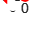


% K_aug(1:4) are your feedback gains, K_aug(5) is your integral gain (Ki)
%% ===== Cart-Pendulum Animation + Live Plots (x and theta) =====
% Requires: out (Simulink.SimulationOutput) containing:
%   out.x_out (timeseries), out.theta_out (timeseries), out.tout (double)

% ---------- Extract signals ----------
t = out.tout(:);
x = out.x_out.Data(:);
theta = out.theta_out.Data(:);

% If theta looks like degrees, convert to rad
if max(abs(theta)) > 2*pi
    theta = deg2rad(theta);
end

% Your sign convention fix:
theta = -theta;

% ---------- Visualization parameters ----------
l     = 0.3;     % rod length (m)
cartW = 0.25;    % cart width (m)
cartH = 0.12;    % cart height (m)

follow_cart = true;
half_window = 0.9;     % view half-width (m)

% Playback speed:
slow = 1;              % 1=real-time, 0.5=2x faster, 3=3x slower

% Frame selection (smoothness vs CPU)
N = numel(t);
targetFrames = 1500;    % increase for smoother, decrease for lighter
step = max(1, floor(N/targetFrames));
idx = 1:step:N;
if idx(end) ~= N, idx(end+1) = N; end

% ---------- Figure layout ----------
figure(1); clf
set(gcf,'Color','w');

tl = tiledlayout(2,2,'TileSpacing','compact','Padding','compact');

% --- Tile 1: Animation (spans two rows in first column)
axAnim = nexttile(tl, [2 1]);
hold(axAnim,'on'); grid(axAnim,'on');
xlabel(axAnim,'x (m)'); ylabel(axAnim,'y (m)');
title(axAnim,'Cart-Pendulum');

xminAll = min(x) - 0.6; xmaxAll = max(x) + 0.6;
ymin = -0.1; ymax = l + cartH + 0.25;
axis(axAnim,[xminAll xmaxAll ymin ymax]);
axis(axAnim,'equal');

% rail
plot(axAnim,[xminAll xmaxAll],[0 0],'k-','LineWidth',1);

% graphics objects
cartPatch = patch(axAnim,'XData',[],'YData',[], ...
    'FaceColor',[0.2 0.6 0.9],'EdgeColor','k');
rodLine = plot(axAnim,[0 0],[0 0],'k-','LineWidth',3);
bobPlot = plot(axAnim,0,0,'ro','MarkerSize',10,'MarkerFaceColor','r');

timeText = text(axAnim, 0.02, 0.95, '', 'Units','normalized', ...
    'FontWeight','bold', 'BackgroundColor','w', 'Margin',3);

% --- Tile 2: x(t)
axX = nexttile(tl, 2);
hold(axX,'on'); grid(axX,'on');
title(axX,'Cart displacement x(t)');
xlabel(axX,'t (s)'); ylabel(axX,'x (m)');

% faint full trajectory for context (optional)
plot(axX, t, x, 'k:', 'LineWidth', 1);

xLiveLine = plot(axX, t(1), x(1), 'b-', 'LineWidth', 2);
xMarker   = plot(axX, t(1), x(1), 'bo', 'MarkerFaceColor','b');

xlim(axX,[t(1) t(end)]);
padx = 0.05*(max(x)-min(x) + eps);
ylim(axX,[min(x)-padx max(x)+padx]);

% --- Tile 3: theta(t)
axTh = nexttile(tl, 4);
hold(axTh,'on'); grid(axTh,'on');
title(axTh,'Pendulum angle \theta(t)');
xlabel(axTh,'t (s)'); ylabel(axTh,'\theta (rad)');

plot(axTh, t, theta, 'k:', 'LineWidth', 1);

thLiveLine = plot(axTh, t(1), theta(1), 'r-', 'LineWidth', 2);
thMarker   = plot(axTh, t(1), theta(1), 'ro', 'MarkerFaceColor','r');

xlim(axTh,[t(1) t(end)]);
padth = 0.1*(max(theta)-min(theta) + eps);
ylim(axTh,[min(theta)-padth max(theta)+padth]);

% ---------- Animation loop (time-synced) ----------
tic;
t0 = t(idx(1));

for ii = 1:numel(idx)
    k = idx(ii);

    xc = x(k);
    th = theta(k);

    % cart rectangle
    Xc = [xc-cartW/2, xc+cartW/2, xc+cartW/2, xc-cartW/2];
    Yc = [0, 0, cartH, cartH];

    % pivot
    px = xc; py = cartH;

    % tip (upright when theta=0)
    tipx = px + l*sin(th);
    tipy = py + l*cos(th);

    % update animation objects
    set(cartPatch,'XData',Xc,'YData',Yc);
    set(rodLine,'XData',[px tipx],'YData',[py tipy]);
    set(bobPlot,'XData',tipx,'YData',tipy);
    set(timeText,'String',sprintf('t = %.2f s', t(k)));

    if follow_cart
        xlim(axAnim,[xc-half_window, xc+half_window]);
        ylim(axAnim,[ymin ymax]);
    end

    % update live plots up to current k
    set(xLiveLine, 'XData', t(1:k), 'YData', x(1:k));
    set(xMarker,   'XData', t(k),   'YData', x(k));

    set(thLiveLine,'XData', t(1:k), 'YData', theta(1:k));
    set(thMarker,  'XData', t(k),   'YData', theta(k));

    drawnow;

    % time sync (slow-motion factor)
    target  = slow*(t(k) - t0);
    elapsed = toc;
    pause(max(0, target - elapsed));
end